# Επιστημονικός Υπολογισμός

## Εργαστηριακή Άσκηση 2023

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Στοιχεία Υπολογιστικού Συστήματος

Για να βρεθούν κάποιες από τις ζητούμενες πληροφορίες χρησιμοποιήθηκαν τα παρακάτω:

blas = version('-blas')

blas = 'OpenBLAS 0.3.21'

lapack = version('-lapack')

lapack = 'NAG Performance Components (NPC) Release 1.0.4, supporting Linear Algebra PACKage (LAPACK 3.9.1)'

Matlab_Version = version

Matlab_Version = '23.2.0.2485118 (R2023b) Update 6'

%bench % (Μπαίνει σαν σχόλιο για να μην τρέξει αυτόματα)

## **1. Χρονομετρήσεις**

### Μετρήσεις 

n_repeats = 3;

tchol1=zeros(1,20);

for i = 1:n_repeats
    for n = 100:100:2000
        % Generate a dense n x n symmetric, positive definite matrix
        A = rand(n,n); % generate a random n x n matrix

        % construct a symmetric matrix using either
        A = 0.5*(A+A');

        % since A(i,j) < 1 by construction and a symmetric diagonally dominant matrix
        %   is symmetric positive definite, which can be ensured by adding nI
        A = A + n*eye(n);

        time_me = @() chol(A);

        tchol1(n/100) = tchol1(n/100) + timeit(time_me,1);

    end
end
tchol1 = tchol1 ./i

tchol1 =     0.0000    0.0003    0.0007    0.0012    0.0017    0.0023    0.0037    0.0038    0.0045    0.0050    0.0047    0.0056    0.0062    0.0068    0.0094    0.0113    0.0124    0.0137    0.0162    0.0184


tchol2=zeros(1,15);

for i = 1:n_repeats
    for n = 150:100:1550
        % Generate a dense n x n symmetric, positive definite matrix
        A = rand(n,n); % generate a random n x n matrix

        % construct a symmetric matrix using either
        A = 0.5*(A+A');

        % since A(i,j) < 1 by construction and a symmetric diagonally dominant matrix
        %   is symmetric positive definite, which can be ensured by adding nI
        A = A + n*eye(n);

        time_me = @() chol(A);

        tchol2((n-50)/100) = tchol2((n-50)/100) + timeit(time_me,1);

    end
end
tchol2 = tchol2 ./i

tchol2 =     0.0001    0.0006    0.0012    0.0015    0.0020    0.0026    0.0032    0.0040    0.0049    0.0044    0.0052    0.0062    0.0069    0.0092    0.0102


### 1.1. Εύρεση κυβικής συνάρτησης

n = 100:100:2000;

p3 = polyfit(n,tchol1,3)

p3 =     0.0000   -0.0000    0.0000   -0.0012


Σημείωση: Η εκτέλεση της polyfit μπορεί να μας επιστρέψει άλλους συντελεστές.

### 1.2. Πρόβλεψη χρόνου Εκτέλεσης

prediction1 = polyval(p3,n)

prediction1 =    -0.0003    0.0004    0.0010    0.0016    0.0021    0.0025    0.0030    0.0034    0.0039    0.0045    0.0051    0.0059    0.0068    0.0078    0.0090    0.0104    0.0121    0.0140    0.0161    0.0186


k = 150:100:1550;
prediction2 = polyval(p3,k)

prediction2 =     0.0001    0.0007    0.0013    0.0018    0.0023    0.0027    0.0032    0.0037    0.0042    0.0048    0.0055    0.0063    0.0073    0.0084    0.0097


### **1.3. Ακρίβεια Πρόβλεψης**

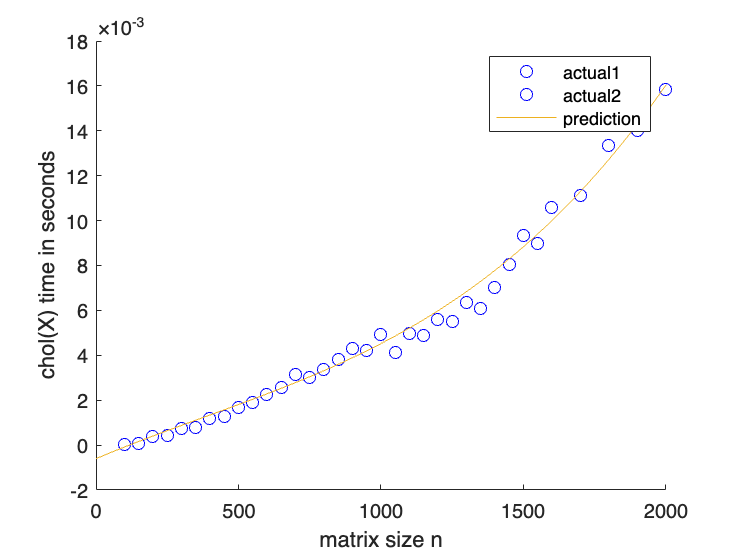

figure
hold on
plot(n,tchol1,'bo')
plot(k,tchol2,'bo')
plot(0:1:2000,polyval(p3,0:1:2000))
hold off
xlabel('matrix size n');
ylabel('chol(X) time in seconds');
legend('actual1','actual2','prediction')

### **1.4. Επανάληψη με χρήση πολυωνύμων διαφορετικών βαθμών**

#### **Πρόβλεψη με πολυώνυμο 2ου βαθμού**

p2 = polyfit(n,tchol1,2);

figure
hold on
plot(n,tchol1,'bo')
plot(k,tchol2,'bo')
plot(0:1:2000,polyval(p2,0:1:2000))
hold off
xlabel('matrix size n');
ylabel('chol(X) time in seconds');
legend('actual1','actual2','prediction')

#### **Πρόβλεψη με πολυώνυμο 4ου βαθμού**

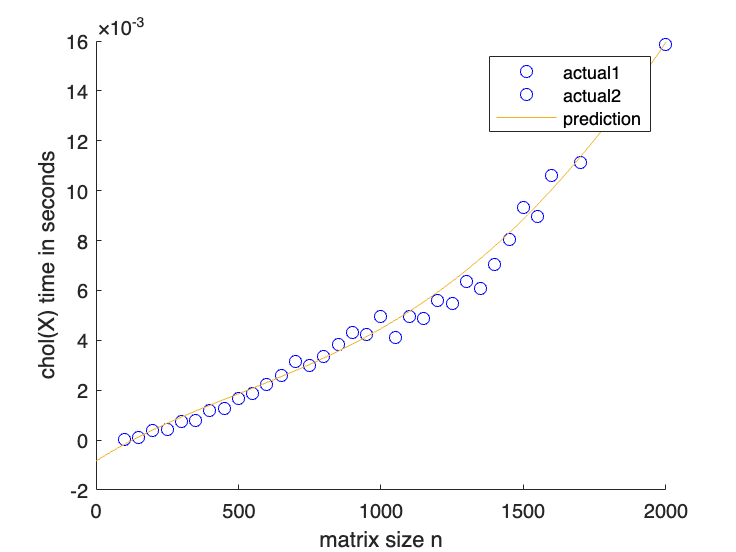

p4 = polyfit(n,tchol1,4);

figure
hold on
plot(n,tchol1,'bo')
plot(k,tchol2,'bo')
plot(0:1:2000,polyval(p4,0:1:2000))
hold off
xlabel('matrix size n');
ylabel('chol(X) time in seconds');
legend('actual1','actual2','prediction')

## **2.Ειδικοί επιλυτές και αραιά μητρώα **

Για τις ανάγκες της άσκησης παράγαμε 2 συναρτήσεις για την συμπίεση και την αποσυμπίεση μητρώων ζώνης.	 

`bandmatrix_1067400()`

([Άνοιγμα Ορισμού](matlab:open('./bandmatrix_1067400.m')))

Αυτή η συνάρτηση παίρνει ένα απλό διαγώνιο μητρώο και το συμπιέζει σύμφωνα με το [πρότυπο της LAPACK](https://netlib.org/lapack/lug_old/node113-.html).

`debandmatrix_1067400()`

([Άνοιγμα Ορισμού](matlab:open('./debandmatrix_1067400.m')))

Αυτή η συνάρτηση παίρνει ένα μητρώο το οποίο είναι συμπιεσμένο σύμφωνα με το [πρότυπο της LAPACK](https://netlib.org/lapack/lug_old/node113-.html) και το αποσυμπιέζει.

### Επιλυτής Τριδιαγώνιων Συστημάτων

Τυχαίο Τριδιαγώνιο μητρώο

% Creating A
n = 5;  % Size of the matrix
a = randi(10, n, 1);  % Lower diagonal
b = randi(10, n, 1);    % Main diagonal
c = randi(10, n, 1);  % Upper diagonal
A_sparse = spdiags([a b c], -1:1, n, n);  % Construct tridiagonal matrix
A_full = full(A_sparse);
A = bandmatrix_1067400(A_full)

A =      0     8     4     9    10
     8     8     8     8     8
     5     1     6     2     0



%Creating B
B = randi(10, n, 1)

B =      4
     8
     1
     9
     3


Δημιουργήσαμε την παρακάτω συνάρτηση ως επιλυτή τριδιαγωνίων μητρώων.

`tdbmsolver_1067400()`

([Άνοιγμα Ορισμού](matlab:open('./tdbmsolver_1067400.m')))

Αυτή η συνάρτηση παίρνει ένα μητρώο το οποίο είναι συμπιεσμένο σύμφωνα με το [πρότυπο της LAPACK](https://netlib.org/lapack/lug_old/node113-.html) και το δεξί μέρος ενός συστήματος και υπολογίζει τη λύση του συστήματος.

x1 = tdbmsolver_1067400(A,B)

x1 =     2.6538
   -2.1538
    2.9904
   -2.3077
    0.9519


x2 = A_full\B % to compare to our results

x2 =     2.6538
   -2.1538
    2.9904
   -2.3077
    0.9519



%B_reconstructed = A_full*x1

## **3.Τανυστές**

Για τον έλεγχο αυτού του ερωτήματος απαιτείται η εγκατάσταση του tensor toolbox. Μπορείτε να το εγκαταστήσετε από [εδώ](https://www.tensortoolbox.org). Ύστερα θα χρειαστεί να τρέξετε τα παρακάτω:

%addpath('the/path/to/the/toolbox'); 
%savepath;

### **Αρχικοποίηση**

clear; tol=1e-8;nd=3; rng(0); err=zeros(1,nd+2);
ndim=[2,3,4]; Atemp= randi(5,ndim); Btemp=randi(4,ndim); X=randi ([ -1 ,1] ,max(ndim) ,1) ; A=tensor (Atemp) ; B=tensor (Btemp) ;

`ttv_1067400(X,V,N)`

([Άνοιγμα Ορισμού](matlab:open('./ttv_1067400.m')))

Πολλαπλασιασμός του τανυστή X με το διάνυσμα V κατά τρόπο N.

Y = ttv_1067400(Atemp, [1;-1], 1)

Y =      0    -1     2    -1
    -4     0     4     3
     3    -4    -2     0


### **Έλεγχος Σωστής λειτουργίας**

try
    for k=1:nd
        err(k)=norm(ttv_1067400(Atemp,X(1:ndim(k) ,1),k)-double(ttv(A,X(1:ndim(k) ,1),k)))
    end
    assert(max(err)<tol ,'ttv modal multiplication fails')
catch ME1
end

err =      0     0     0     0     0


err =      0     0     0     0     0


err =      0     0     0     0     0


try
    err (nd+1) = norm( tensor ( ttt_1067400 (A,B) ) - ttt (A,B) ) ;
    assert ( err (nd+1)<tol , 'ttt outer multiplication fails' )
catch ME2
end
try
    err(nd + 2) = abs(ttt_1067400(A,B,'all') -double(ttt(A, B, [1:nd])));
    assert (err(nd+2)<tol,'ttt inner product fails')
catch ME3
end
if (exist('ME1'))
    ME1.message
end
if (exist('ME2'))
    ME2.message
end

ans = 'Invalid indexing'

if (exist('ME3'))
    ME3.message
end

## **4.Επίλυση ΣΘΟ συστημάτων με PCG **